# Introduction to Synthetic Aperture Radar Using Python and MATLAB

## by Andy Harrison - © 2022 Artech House

### Example 3.4.5 Polar Format Algorithm - Point Targets

% Speed of light (m/s)
c = 299792458;

% Set the range to the center of the image
range_center = 1000; % meters

% Set the target locations and RCS
x_target = [10, -5, 2.5, -2.5]; % meters
y_target = [10, -5, -1, 8]; % meters

rcs = [10, 10, 7, 5]; % m^2

% Set the image x and y spans
x_span = 30; % meters
y_span = 30; % meters

% Set the number of bins in the image
nx = 1024; % Number of bins in x-direction
ny = 1024; % Number of bins in y-direction

% Set the sensor bandwidth and starting frequency
start_frequency = 5e9; % Staring frequency (Hz)
bandwidth = 200e6; % Operating bandwidth (Hz)

% Set the azimuth span of the synthetic aperture
az_start = -1; % degrees
az_end = 1; % degrees

% Choose the window type for the processing
window_type = 'None';

% Set the dynamic range for the image
dynamic_range = 25; % dB

% Set up the azimuth space
r = sqrt(x_span ^ 2 + y_span ^ 2);
da = c / (2.0 * r * start_frequency);
na = round(deg2rad(az_end - az_start) / da);
az = linspace(az_start, az_end, na);

% Set up the frequency space
df = c / (2.0 * r);
nf = floor(bandwidth / df);
frequency = linspace(start_frequency, start_frequency + bandwidth, nf);

% Calculate the signal (k space)
signal = zeros(nf, na);
kx = zeros(nf, na);
ky = zeros(nf, na);
kc = 2 * pi * frequency / c;

% Short hand and helps with computational load
ca = cosd(az);
sa = sind(az);

for i = 1:na
    r_los = [ca(i), sa(i)];
    kx(:, i) = kc .* ca(i);
    ky(:, i) = kc .* sa(i);
    for j = 1:length(x_target)
        r_target = dot(r_los, [x_target(j), y_target(j)]);
        signal(:, i) = signal(:, i) + rcs(j) * exp(1j * 2.0 * kc * r_target)';
        
    end
end


#### Plot the raw phase history data

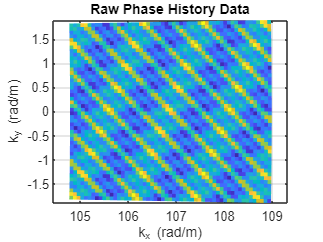

figure; pcolor(kx, ky, real(signal)); shading flat
title('Raw Phase History Data')
xlabel('k_x (rad/m)')
ylabel('k_y (rad/m)')
grid on
axis equal

% Set up the wavenumber space
kxmin = min(min(kx));  kxmax = max(max(kx));
kymin = min(min(ky));  kymax = max(max(ky));
kxp = linspace(kxmin, kxmax);  kyp = linspace(kymin, kymax);
[kxp, kyp] = meshgrid(kxp, kyp);

% Set up the interpolation
F = scatteredInterpolant(kx(:), ky(:), signal(:));

% Perform the interpolation
new_signal = F(kxp, kyp);

#### Plot the reformatted phase history data

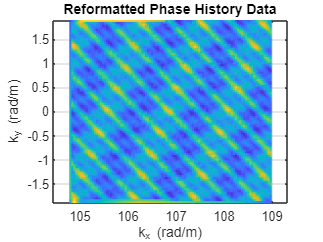

figure; pcolor(kxp, kyp, real(new_signal)); shading flat
title('Reformatted Phase History Data')
xlabel('k_x (rad/m)')
ylabel('k_y (rad/m)') 
grid on
axis equal

% Get the frequency step size
frequency_step = c / (2 * pi) * (kxp(1,2) - kxp(1,1));

% Calculate the maximum scene size and resolution
range_extent = c / (2 * frequency_step);

% Calculate the range window for the pulses
range_window = linspace(-0.5 * range_extent, 0.5 * range_extent, nx);

% Get the frequency step size
frequency_step = c / (2 * pi) * (kyp(2,1) - kyp(1,1));

% Calculate the maximum scene size and resolution
cross_range_extent = c / (2 * frequency_step);

% Calculate the range window for the pulses
cross_range_window = linspace(-0.5 * cross_range_extent, 0.5 * cross_range_extent, ny);

r_signal = fftshift(ifft(new_signal, nx, 2), 2);

kypp = linspace(min(min(ky)), max(max(ky)));

#### Plot the range compressed data

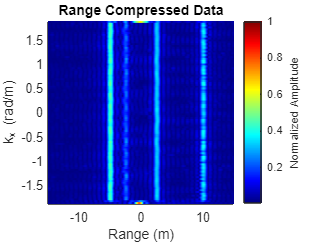

figure; pcolor(range_window, kypp, abs(r_signal)/max(max(abs(r_signal)))); shading flat
xlim([-0.5 * x_span, 0.5 * x_span])
title('Range Compressed Data')
xlabel('Range (m)')
ylabel('k_x (rad/m)')
h = colorbar;
ylabel(h, 'Normalized Amplitude');
colormap jet

#### Plot the focused image

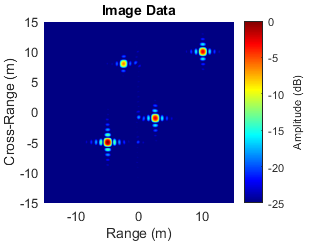

ra_signal = fftshift(ifft(r_signal, ny, 1), 1);
figure; pcolor(range_window, cross_range_window, 20*log10(abs(ra_signal)/max(max(abs(ra_signal))))); shading flat
caxis([-abs(dynamic_range), 0])
xlim([-0.5 * x_span, 0.5 * x_span])
ylim([-0.5 * y_span, 0.5 * y_span])
title('Image Data')
xlabel('Range (m)')
ylabel('Cross-Range (m)')
h = colorbar;
ylabel(h, 'Amplitude (dB)')
colormap jet